# MAE180A - Team Project

Compute inertial pos & vel vectors (ECI) & classical orbital elements (a, e, i, OMEGA, w, M)

    - Current input time & propogate state vector into the future

    - Gauss or Labplace angles- only OD

r0 =           2740.15218494575
          -4844.7413413758
          4500.40986561253


v0 =           2.82144995644283
         -3.78101200484759
          -5.7717896982185


oe0 =           7142.68110052217
       0.00252484348120179
          86.4448851309657
          122.371626636189
          354.094247736544
          146.700364107002


r0_m =           -5680.1632570387
         -1171.93186927101
          4188.63090081872


v0_m =          -3.53098494587745
         -3.32016087975386
         -5.67195330348646


rf =            424.92478332081
         -1463.65214684022
          6824.33912581456


vf =           4.07153701242388
         -6.22227569153085
         -1.70350423536015


oef =           7141.75795650503
        0.0255956248611862
          86.4363232018227
          122.381190850408
          138.175740212349
          325.607855722732


final_distance =           11213.7295566797


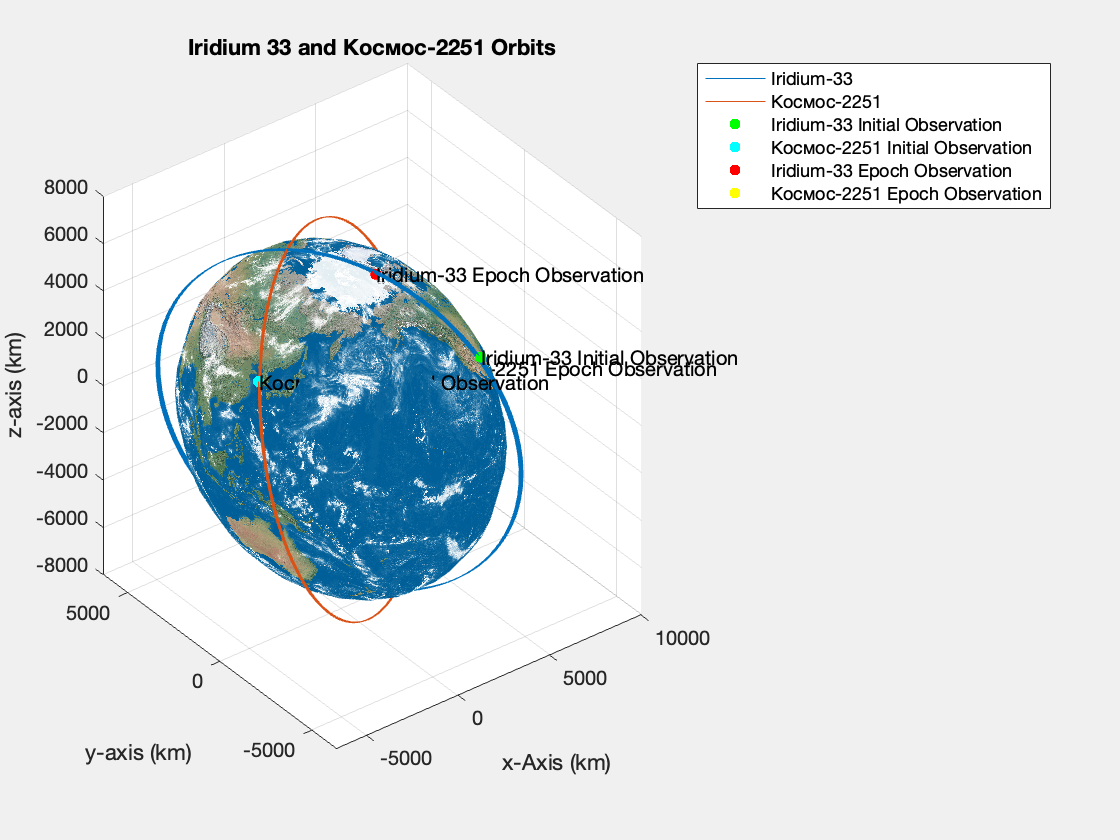

clear,clc;
format long g;
%####################################################################
%# UCSD "OBSERVATIONS" OF EARTH-ORBITING SATELLITES
%# OBSERVED BY: U.S. Strategic Command (Space-track.org)
%# REDUCED BY: PROF AARON J. ROSENGREN
%#
%# SITE LAT: 32.881191 N (deg)
%# SITE LON: 117.233614 W (deg)
%# SITE ALT: 111 (m)
%#
%# TABLE FORMAT: JD, RA (deg), DEC (deg), LST (deg)
%####################################################################
%Elliptical & Inclined Earth Satelite Orbit !!

LAT     = 32.881191;
LONG   = -117.2336137;
ALT     = 111;

% Final Epoch [ JD ]
JD_prop = 2454873.205555555;

% Initial Observations
[JD1, RA1, DEC1, LST1] = deal(2454871.265087747,  52.798193640488,  81.879593064640, 297.183020125837);
[JD2, RA2, DEC2, LST2] = deal(2454871.265782192, 341.586281899396,  74.538612050462, 297.433704756149);
[JD3, RA3, DEC3, LST3] = deal(2454871.266476636, 322.497218402089,  52.518231818061, 297.684389218458);

% Formating for use in algorithm
JD  = [JD1; JD2; JD3];
RA  = [RA1; RA2; RA3];
DEC = [DEC1; DEC2; DEC3];
LST = [LST1; LST2; LST3];

% Orbit Determination
Test = OrbitComp(LAT, LST, ALT, RA, DEC, JD, JD_prop);


% See Iridium 33 Orbit with Earth Model
%   if isfile('Iridium33Cosmos2251Collision.tle')
%       simulateOrbit(JD(2), JD_prop, LAT, LONG)
%   end

function [r0, v0, oe0, rf, vf, oef] = OrbitComp(lat, lst, alt, ra, dec, JD, JD_prop)
%{
Input: Site Latitude (deg), Local Sidereal time (deg), Altitude (m), Right Ascension (deg), 
       Declination (deg), Observation times (JD), Final Epoch state for propogation (JD)
Output: Initial State Vectors (km & km/s), Initial Orbital Elements, 
        Final State Vectors (km & km/s), Final Orbital Elements

Note:
ra & dec are 3x1 vectors containning 3 observations at each respective time tag descriubed by JD array
oe0 & oef are 6x1 vectors describing initial/final Keplerian Orbital Elements 
(Semi-Major Axis, Eccentriciy, Inclination, Right Ascension of Ascending Node, Argument of Periapsis, Mean Anomaly)
%}
    % Gravitational Parameter of attracting body [ km^3/s^2 ]
    const.mu = 398600.4354;
    
    % Earth's Radius [ km ] + altitude of Observation site [ m ]
    Re = 6378.1366+ (alt * 1e-3);
    
    % Earth's inertial rotation rate [ rad/s ] 
    wE = 7.2921159e-5;
    
    % Second Zonal Harmonic coefficient of geopotential
    J2 = 1.0826359e-3;

    % Convert from degrees to radians
    lat = deg2rad(lat);
    lst = deg2rad(lst);
    ra  = deg2rad(ra);
    dec = deg2rad(dec);
    
    % Time of flight from observation 2, to epoch [ sec ] 
    TOF = 86400 * (JD_prop - JD(2));

    % ------ GAUSS ALGORITHM -----------------------------------------------
    
    % Find change in times between observations [ sec ]
    t1 = 86400 * ( JD(1) - JD(2) );
    t3 = 86400 * ( JD(3) - JD(2) );
    
    % R-site matrix in ECI (Radius of each observation, from observed location)
    Rs1    = Re .* [cos(lat).*cos(lst(1)); cos(lat).*sin(lst(1)); sin(lat)];
    Rs2    = Re .* [cos(lat).*cos(lst(2)); cos(lat).*sin(lst(2)); sin(lat)];
    Rs3    = Re .* [cos(lat).*cos(lst(3)); cos(lat).*sin(lst(3)); sin(lat)];
    R_site = [Rs1 Rs2 Rs3];
    
    % Line of Sight Unit Vectors/Matrix
    L1 = [cos(dec(1))*cos(ra(1)); cos(dec(1))*sin(ra(1)); sin(dec(1))];
    L2 = [cos(dec(2))*cos(ra(2)); cos(dec(2))*sin(ra(2)); sin(dec(2))];
    L3 = [cos(dec(3))*cos(ra(3)); cos(dec(3))*sin(ra(3)); sin(dec(3))];
    L  = [L1 L2 L3];
    
    %Intermediate relations
    M = inv(L) * R_site;
    
    % Estimated parameters that lead to finding the middle range magnitude
    a1  = t3 / (t3 - t1);
    a1u = t3 * ( (t3 - t1)^2 - t3^2 ) / ( 6*(t3 - t1) );
    
    a3  = -t1 / (t3 - t1);
    a3u = -t1 * ( (t3 - t1)^2 - t1^2 ) / ( 6*(t3 - t1) );
    
    % Parameters to be used in 8th degree eq
    d1 = M(2,1)*a1 - M(2,2) + M(2,3)*a3;
    d2 = M(2,1)*a1u + M(2,3)*a3u;
    
    C = dot(L2, Rs2);
    
    % Eighth-degree equation - find roots of eqn. NEEDS TO FIT ORBIT !!!CHECK!!!
    syms r2
    eqn = 0 == r2^8 - (d1^2 + 2*C*d1 + norm(Rs2)^2)*r2^6 - 2*const.mu*(C*d2 + d1*d2)*r2^3 - const.mu^2 * d2^2;
    r2  = real( vpa( solve(eqn, r2 > Re) ) );
    
    u = const.mu / r2^3;
    
    % ci coefficients
    c = [ a1 + a1u*u; -1; a3 + a3u*u ]; 
    
    % Initial guess of slant ranges
    syms rho1 rho2 rho3
    eqn1  = c(1)*rho1 == M(1,:) * -c;
    eqn2  = c(2)*rho2 == M(2,:) * -c;
    eqn3  = c(3)*rho3 == M(3,:) * -c;
    rho   = [ solve(eqn1, rho1); solve(eqn2, rho2); solve(eqn3, rho3)  ]; 
    
    % Find Position Vectors ( r2 = r0 initial position vector // used eval to convert to type double)
    r1 = rho(1)*L1 + Rs1;
    r0 = eval( rho(2)*L2 + Rs2 )
    r3 = rho(3)*L3 + Rs3;
    
    % ------------------ Herricks - Gibbs ---------------------------------
    % Angles between vectors, large angles -> GIBBS, else herrickGibbs
    angle12 = vpa( rad2deg( acos(dot(r1,r0) / ( norm(r1) * norm(r0) )) ) );
    
    angle23 = vpa( rad2deg( acos(dot(r0,r3) / ( norm(r0) * norm(r3) )) ) );
    
    % If alpha12 & alpha23 are small, HERRICK-GIBBS alg to find 
    t31 = 86400 * ( JD(3) - JD(1) );
    t21 = 86400 * ( JD(2) - JD(1) );
    Z23 = cross(r0,r3);
    
    % Initial Velocity Vect.
    v0  = eval(      -t3*( (1/(t21*t31) ) + ( const.mu / ( 12*(norm(r1)^3) ) ) )*r1 ...
             + (t3 - t21)*( (1/(t21*t3) ) + ( const.mu / ( 12*(norm(r0)^3) ) ) )*r0 ...
                    + t21*( (1/(t3*t31) ) + ( const.mu / ( 12*(norm(r3)^3) ) ) )*r3 )
    
    % Oribtal elements of Initial Observation State
    oe0    = rv2koe( r0, v0, const.mu, 'deg' )
    state0 =  [ r0 ; v0 ];
    
    % Data from Michael Zheng's group
    r0_m = [-5680.163257038702 -1171.931869271007 4188.630900818716]'
    v0_m = [-3.530984945877453 -3.320160879753856 -5.671953303486460]'
    oe0_m = rv2koe( r0_m, v0_m, const.mu, 'deg' );
    state0_m= [ r0_m ; v0_m ];
    rf_m = [6550.986346931877 2407.640839182386 -1458.597705246260];
    vf_m = [0.632286857251846 2.479520006304164 7.034873651853970];
    oef_m = rv2koe( rf_m, v0_m, const.mu, 'deg' );
    % Acceleration due to Earth's Oblateness
    n = sqrt( const.mu/oe0(1)^3 );
    p = oe0(1) * sqrt( 1 - oe0(2)^2 );
    num = 3*J2*(Re^2)*n;
    const.dOm = ( (-num) / (2*p^2) ) * ( cosd(oe0(3)) );
    const.dw  = ( ( num) / (4*p^2) ) * (5*(cosd(oe0(3))^2) - 1);
    const.M0  = ( ( num) / (4*p^2) ) * (3*(cosd(oe0(3))^2) - 1) * sqrt( 1 - oe0(2)^2 );
    %const.dOm.fromHW = ( (-3*n*J2) / ( 2*( (1-oe0(2)^2)^2) ) ) * (Re/oe0(1))^2 * (cosd(oe0(3)))
    %const.dW.fromHW = ( (3*n*J2) / ( 4*((1-oe0(2)^2)^2) ) )   * (Re/oe0(1))^2 * (4-5*sind(oe0(3))^2)

    % 1 METHOD TO PROPOGATE -------------------------------------------
    % Specify number of points in integration
    Nt    = 2000;
    tspan = linspace( 0, TOF, Nt );
    
    % Set integrator options
    const.tol = 1e-11;
    opt = odeset('RelTol', const.tol, 'AbsTol', const.tol);
    const.ode = 'ode113';
    
    % Integrate the equations of motion using ode113
    [ ~ , statet ] = ode113( @twobody, tspan, state0, opt, const );
    [ ~ , statet_m ] = ode113( @twobody, tspan, state0_m, opt, const );
    % Extract Position & Velocity vectors of our data and other group's data( to plot )
    r = statet(:,1:3)';
    v = statet(:,4:6)';

    r_m = statet_m(:,1:3)';
    v_m = statet_m(:,4:6)';
    % Final Position, Velocity, & Oribital Elements!
    rf  = r(:,end)
    vf  = v(:, end)
    oef = rv2koe( r(:,end), v(:, end), const.mu, 'deg' )

    % -----------------------------------------------------------------
    %determine distance between final position
    
    dist_r = rf-rf_m;
    final_distance =  abs(norm(dist_r))

    % -----------------------------------------------------------------

    % Plot Graph
    plotGraph(r,r0,rf,r_m,r0_m,rf_m)


    
        % Initial Energy
        %E0 = .5 * dot(v0',v0) - const.mu/norm(r0)
        % Final Energy
        %Ef = .5 * dot(vf',vf) - const.mu/norm(rf)

        % Period [ sec ]
        %T = 2*pi * sqrt(oe0(1)^3 / const.mu)

    
    % 2nd method to propogate ------------------------------ ( check if matches prev. results )
    %  [ rf, vf ] = koe2rv(oe0, const.mu, TOF, 'deg')
    %  oef = rv2koe(rf, vf, const.mu, 'deg')
        % NEED TO LEARN HOW TO PLOT THIS, THIS METHOD IS WAY MORE ACCURATE!!!
        % TAKES LESS LINES OF CODE TOO

    
end


function [ koe ] = rv2koe( r, v, mu, angletype )
%{
FILENAME: rv2koe
DESCRIPTION: This function computes the classical (Keplerian) orbit
elements given the Cartesian position and velocity vectors, the
gravitational parameter of the attracting body, and the desired angletype
NOTES: This function can handle eccentric and hyperbolic orbits
INPUTS:
r = Cartesian position vector [ km ]
v = Cartesian velocity vector [ km/s ]
mu = gravitational parameter of attracting body [ km^3/s^2 ]
angletype = string indicating desired angletype for inputs
'deg' = degrees, 'rad' = radians
OUTPUTS:
koe = vector which contains the classical orbit elements
[ a; e; i; Om; w; M ]
FUNCTIONS/SCRIPTS CALLED:
none
CALLED BY:
...
MODIFICATIONS:
1-Feb-2021 | Aaron J. Rosengren - Original
REFERENCES:
MAE 180A - Winter 2023, Lesson 3 Notes
%}
    % Create empty vector for keplerian elements
    koe = zeros(6, 1);
    % Conversions
    r2d = 180/pi;
    % Coordinate frame unit vectors
    I = [1 0 0]; J = [0 1 0]; K = [0 0 1];
    rhat = r/norm(r); % position unit vector [km]
    h = cross(r,v); % angular momentum {h = r x v}
    hhat = h/norm(h); % normalized angular momentum
    nhat = cross(K,h)/norm(cross(K,h)); % normalized ascending node vector
    % Eccentricity
    e = (1/mu)*cross(v,h) - rhat; % eccentricity vector
    koe(2) = norm(e);
    energy = (1/2)*dot(v,v) - mu/norm(r); % energy, km^2/s^2
    % If energy < 0, the orbit is closed (periodic)
    % Semi-major axis (a) and parameter (p)
    if koe(2) ~= 1
        koe(1) = -mu/(2*energy); % {energy = -mu/(2*a)}
        p = koe(1)*(1 - koe(2)^2);
    else
        koe(1) = inf;
        p = hmag^2/mu;
    end
    % Inclination (i) of orbit
    koe(3) = acos(dot(K,hhat));
    % If i < 90 deg, the elliptical orbit is a direct (prograde) orbit
    % Right ascension of the ascending node (Omega)
    koe(4) = mod(atan2(dot(J,nhat),dot(I,nhat)), 2*pi);
    % Argument of periapsis (w)
    koe(5) = mod(atan2(dot(hhat,cross(nhat,e)),dot(nhat,e)), 2*pi);
    % True anomaly (f) at epoch [rad]
    f = vpa( mod(atan2(dot(hhat,cross(e,r)),dot(e,r)), 2*pi) );
    if koe(1) > 0 % ----- eccentric orbit ----- %
        % Eccentric anomaly (E) at epoch [rad]
        E = 2*atan2(sqrt(1 - koe(2))*tan(f/2),sqrt(1 + koe(2)));
        % Mean anomaly (M) at epoch [rad]
        koe(6) = mod((E - koe(2)*sin(E)), 2*pi);
    else % ----- hyperbolic orbit ----- %
        % Hyperbolic anomaly (H) at epoch [rad]
        H = 2*atanh(sqrt(koe(2) - 1)*tan(f/2)/sqrt(koe(2) + 1));
        % Hyperbolic mean anomaly (N) at epoch [rad]
        koe(6) = mod((koe(2)*sinh(H) - H), 2*pi);
    end
    if(strcmp(angletype, 'deg'))
        koe(3:end) = koe(3:end)*r2d;
    end
end

function [ r, v ] = koe2rv( koe, mu, TOF, angletype )
%{
FILENAME: koe2rv
DESCRIPTION: This function computes the cartesian position and velocity
vectors given the classical orbit elements, gravitational
parameter of the attracting body, time of flight, and angletype
used for the inputs.
NOTES: This function can handle eccentric and hyperbolic orbits
INPUTS:
koe = vector which contains the classical orbit elements
[ a; ec; in; Om; w; M ]
a - semimajor axis [ km ]
ec - eccentricity [ ]
in - inclination [ rad ]
w - argument of periapsis [ rad ]
Om - longitude of the ascending node [ rad ]
M0 - mean or hyperbolic anomaly at epoch [ rad ]
mu = gravitational parameter of attracting body [ km^3/s^2 ]
TOF = time which has elapsed since the epoch time t0 [ s ]
angletype = string indicating desired angletype for inputs
'deg' = degrees, 'rad' = radians
OUTPUTS:
r = Cartesian position vector [ km ]
v = Cartesian velocity vector [ km/s ]
FUNCTIONS/SCRIPTS CALLED:
none
CALLED BY:
...
MODIFICATIONS:
1-Feb-2021 | Aaron J. Rosengren - Original
REFERENCES:
MAE 180A - Winter 2023, Lesson 3 Notes
%}
    % Classical orbit elements
    a  = koe(1);
    ec = koe(2);
    in = koe(3);
    Om = koe(4);
    w  = koe(5);
    M0 = koe(6);
    if(strcmp(angletype, 'deg'))
        in = deg2rad(in);
        Om = deg2rad(Om);
        w  = deg2rad(w);
        M0 = deg2rad(M0);
    end
    % Mod out by pi or 2pi
    in = mod(in, pi);
    Om = mod(Om, 2*pi);
    w  = mod(w, 2*pi);
    M0 = mod(M0, 2*pi);
    % Orbital mean motion [ rad/s ]
    nm = sqrt(mu/abs(a)^3);
    % Mean anomaly [ rad ]
    M  = M0 + nm*TOF;
    if a > 0 % ----- eccentric orbit ----- %
        % Compute eccentric anomaly
        % A priori estimate
        j = 1;
        if -pi < M < 0 || M > pi
            E(j) = M - ec;
        else
            E(j) = M + ec;
        end
        % Newton iteration to find eccentric anomaly
        % Algorithm [goal: find E so f = 0]
        f_E(j) = E(j) - ec*sin(E(j)) - M;
        while abs(f_E(j)) > 1e-11
            E(j + 1) = E(j) - f_E(j)/(1 - ec*cos(E(j)));
            j = j + 1;
            f_E(j) = E(j) - ec*sin(E(j)) - M;
        end
        % Converged eccentric anomaly [ rad ]
        E = E(j);
        % True anomaly [ rad ]
        f = mod(2*atan(sqrt((1 + ec)/(1 - ec))*tan(E/2)), 2*pi);
    else % ----- hyperbolic orbit ----- %
        % Compute hyperbolic anomaly
        % A priori estimate
        j = 1;
        H(j) = M;
        % Newton iteration to find hyperbolic anomaly
        % Algorithm [goal: find H so f = 0]
        f_H(j) = ec*sinh(H(j)) - H(j) - M;
        while abs(f_H(j)) > 1e-11
            H(j + 1) = H(j) - f_H(j)/(ec*cosh(H(j)) - 1);
            j = j + 1;
            f_H(j) = ec*sinh(H(j)) - H(j) - M;
        end
        % Converged hyperbolic anomaly [ rad ]
        H = H(j);
        % True anomaly [ rad ]
        f = mod(2*atan(sqrt((ec + 1)/(ec - 1))*tanh(H/2)), 2*pi);
    end
    % Argument of latitude [ rad ]
    th = w + f;
    % Magnitude of position vector [ km ]
    r  = a*(1 - ec^2)/(1 + ec*cos(f)); % trajectory equation
    % Magnitude of velocity vector [ km/s ]
    v  = sqrt(mu*(2/r - 1/a)); % vis-viva equation
    % Ascending node vector
    nhat = [ cos(Om) ; sin(Om) ; 0 ];
    rT   = [ -cos(in)*sin(Om) ; cos(in)*cos(Om) ; sin(in) ];
    gamma = atan2(ec*sin(f), 1 + ec*cos(f)); % [ rad ]
    % Normalized position and velocity vectors
    rhat = cos(th)*nhat + sin(th)*rT; % [ km ]
    vhat = sin(gamma - th)*nhat + cos(gamma - th)*rT; % [ km/s ]
    % Position and velocity vectors
    r = r*rhat; % [ km ]
    v = v*vhat; % [ km/s ]
end

function dx = twobody( ~, x, const)
%{ 
Function handle for keplerian dynamics
INPUTS:
    x       = state vector (6x1) [ r; v]
              r - inertial position vector in N frame components
              v - inertial velocity vector in N frame components
    mu      = Gravitational Parameter of attracting body [ km^3/s^2 ]
OUTPUTS:
    dx = state differential (6x1) [ dr; dv ]
%}
    % Intertial Position & Velocity vectors
    r = x(1:3);
    v = x(4:6);
    
    %acceleration due to J2, Earths oblateness!
    accel_J2 = [const.dOm; const.dw; const.M0];
    
    % State differential (add for earth oblateness model I THINK) + accel_J2
    dx = [ v; -const.mu/norm(r)^3*r + accel_J2];
end

function plotGraph(r,r0,rf,r_m,r0_m,rf_m)
    %Earth sized sphere
    [x,y,z] = sphere;
    x = x*6378.14;
    y = y*6378.14;
    z = z*6378.14;
    figure
    set(gcf,'Visible','on')
    s=surf(x,y,z);
    imData = imread('earth.jpg');
    img = flip(imData ,1);
    ch = get(gca,'children');
    set(ch,'facecolor','texturemap','cdata',img,'edgecolor','none');
    rotate(s,[0 0 1],62)
    hold on
    % Plot Orbits
    plot3( r(1,:), r(2,:), r(3,:), 'Linewidth', .05)
    hold on
    plot3( r_m(1,:), r_m(2,:), r_m(3,:), 'Linewidth', .05)
    plot3(r0(1,:), r0(2,:), r0(3,:), '.', 'color','g', 'Markersize', 15)
    plot3(r0_m(1,:), r0_m(2,:), r0_m(3,:), '.', 'color','c', 'Markersize', 15)
    text(r0(1,:), r0(2,:), r0(3,:),'Iridium-33 Initial Observation')
    text(r0_m(1,:), r0_m(2,:), r0_m(3,:),'Космос-2251 Initial Observation')
    plot3(rf(1), rf(2), rf(3), '.', 'color', 'r', 'Markersize', 15)
    plot3(rf_m(1), rf_m(2), rf_m(3), '.', 'color', 'y', 'Markersize', 15)
    text(rf_m(1), rf_m(2), rf_m(3),'Космос-2251 Epoch Observation')
    text(rf(1), rf(2), rf(3),'Iridium-33 Epoch Observation')
    title('Iridium 33 and Космос-2251 Orbits')
    xlabel('x-Axis (km)'); ylabel('y-axis (km)'); zlabel('z-axis (km)'); 
    legend('','Iridium-33','Космос-2251','Iridium-33 Initial Observation','Космос-2251 Initial Observation','Iridium-33 Epoch Observation','Космос-2251 Epoch Observation')
end

function  simulateOrbit(JD0, JDF, lat, lon)
    startTime  = datetime(JD0,'convertfrom','juliandate','Format', 'dd-MMM-yyyy HH:mm:ss');
    stopTime   = datetime(JDF,'convertfrom','juliandate','Format', 'dd-MMM-yyyy HH:mm:ss');
    sampleTime = 60;
    orbit = satelliteScenario(startTime,stopTime,sampleTime);
    sat = satellite(orbit,"Iridium33Cosmos2251Collision.tle");
    show(sat)
    groundTrack(sat,"LeadTime",1200);
    loc = ["Aaron Rosengren UCSD Office"];
    gs = groundStation(orbit,"Name",loc,"Latitude",lat, "Longitude", lon);
    play(orbit)
end